There are currently 3 defined kernel types:

EQ - exponential Quadratic (SE squared exponential)

RQ - Rational Quadratic (alpha=1)

Matern52

These kernels can be added subtracted multiplied and divided

The GP class takes a mean function and a kernel.

it then can be conditioned on data x and y and can then be trained using mean aposteriori HP selection.

f1 = @(x) (6*x-2).^2.*sin(12*x-4);%.*sin(24*x-1);

xx = lhsdesign(100,1);
yy = f1(xx);

x1 = [0;lhsdesign(100000,1);1];
y1 = f1(x1)+normrnd(0*x1(:,1),0*x1(:,1)+0.5);

a = means.zero()

a =   zero with properties:

         meanz: {[1×1 means.zero]}
        coeffs: {[0]}
    operations: []



d = kernels.EQ(1,0.1)+kernels.Matern52(1,0.1);

d.signn = 0.5;

Z = KISSGP(a,d,100);

tic
Z1 = Z.condition(x1,y1,0,1);
toc

Elapsed time is 1.392500 seconds.


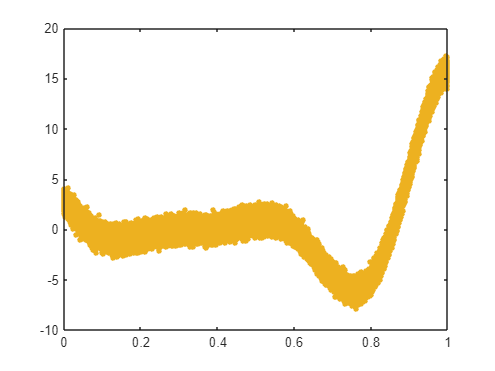

figure
utils.plotLineOut(Z1,1,1)
hold on
plot(xx,yy,'.')
plot(x1,y1,'.','MarkerSize',12,'LineWidth',3)

tic
[Z2] = Z1.train();
toc

Elapsed time is 3.532430 seconds.


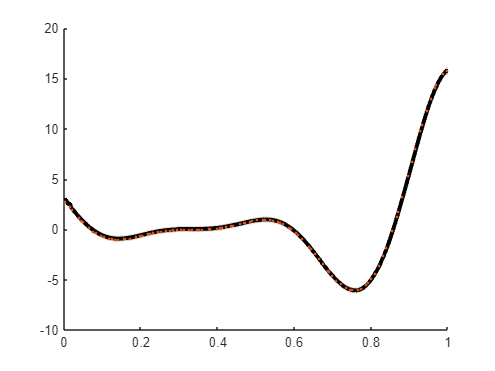

figure
hold on
utils.plotLineOut(Z2,1,1)
plot(xx,yy,'.')

%plot(x1,y1,'+','MarkerSize',12,'LineWidth',3)

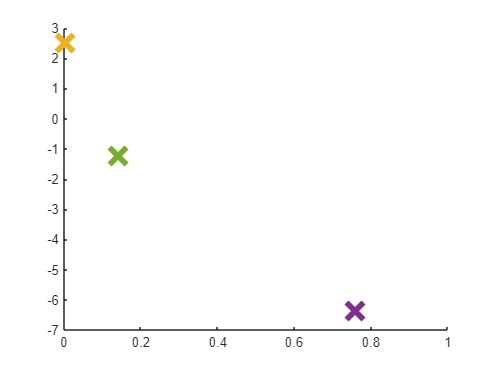

figure
hold on
tic
for i = 1:5
    [x{i},R{i}] = BO.argmin(@BO.LCB,Z2);
    plot(x{i},R{i},'x','MarkerSize',18,'LineWidth',4)
end
xlim([0 1])

toc

Elapsed time is 0.753567 seconds.
